# SLCO4A - Aula Prática 5

## Sistemas

### Classificação de sistemas

#### SISO - Single-Input Single-Output 

a) A relação que descreve um sistema S é $y\left(t\right)=x\left(t-2\right)$. Compute e plot a resposta do sistema para um sinal de entrada $x\left(t\right)=\textrm{tcos}\left(2\pi \;t\right)$, $0\le t\le 3$.

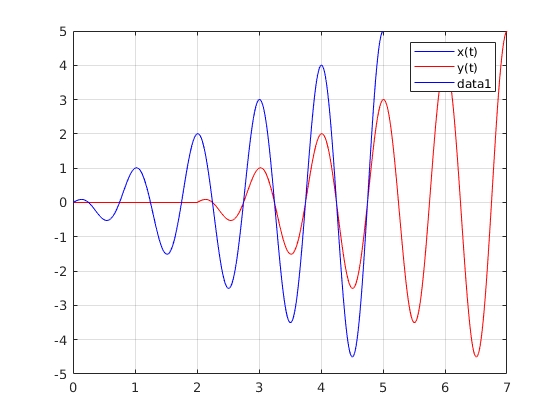

t = 0:0.01:5;
x = t.*cos(2*pi*t);
plot(t, x, 'b')
hold on
plot(t+2, x, 'r')
grid on
legend('x(t)', 'y(t)')
t = 0:0.01:5;
x = t.*cos(2*pi*t);
plot(t, x, 'b')

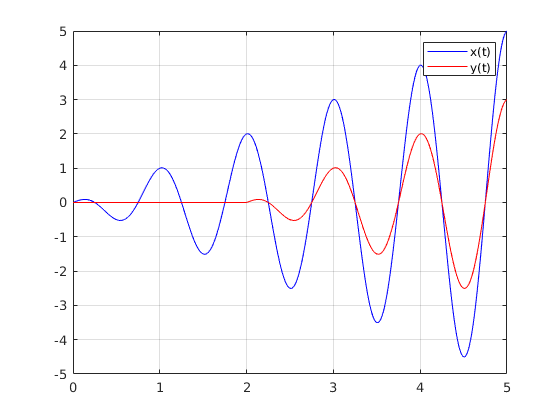


for i=1:length(t)
    if t(i) <= 2
        y(1, i) = 0;
    else
        y(1, i) = (t(i)-2).*cos(2*pi*(t(i)-2));
    end
end
figure
plot(t,x, 'b', t, y, 'r')
legend('x(t)', 'y(t)')
grid on

#### MISO - Multiple-Input Single-Output 

b) Suponha que um sistema MISO S  é descrito pela relação entrada saída $y\left(t\right)=x_1 \left(t\right)+x_2 \left(t\right)x_3 \left(t\right)$. Compute e plot a saída do sistema se os sinais de entrada são dados por $x_1 \left(t\right)=u\left(t\right)-u\left(t-3\right)$, $x_2 \left(t\right)=t\;\sin \left(t\right)$ e $x_3 \left(t\right)=t\;\cos \left(t\right)$, $0\le t\le 4$.

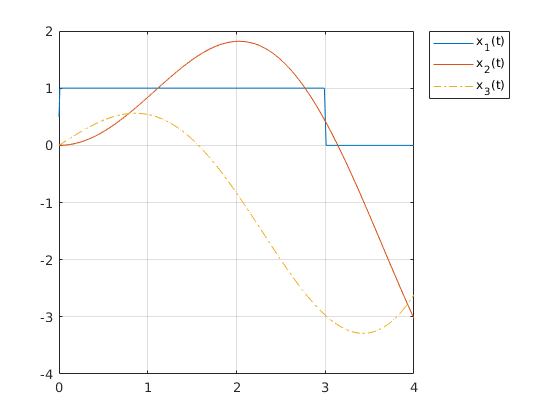

t = 0:0.01:4;
x1 = heaviside(t) - heaviside(t-3);
x2 = t.*sin(t);
x3 = t.*cos(t);
plot(t, x1, t, x2, '-', t, x3, '-.')
legend('x_1(t)', 'x_2(t)', 'x_3(t)', "Location","bestoutside")
grid on

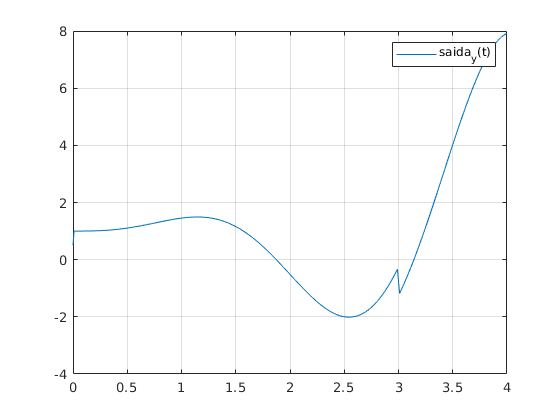

y = x1+x2.*x3;
plot(t, y)
grid on
legend('saida_y(t)')

#### SIMO - Single-Input Multiple-Output 

c) Suponha que um sistema SIMO S  é descrito pelas relações  $y_1 \left(t\right)=x_1^2 \left(t\right)$e $y_2 \left(t\right)=1-3x_1 \left(t\right)$. Compute e plot a saída do sistema se o sinal de entrada é dado por $x_1 \left(t\right)=t\;\cos \left(t\right)$, $0\le t\le 4$.

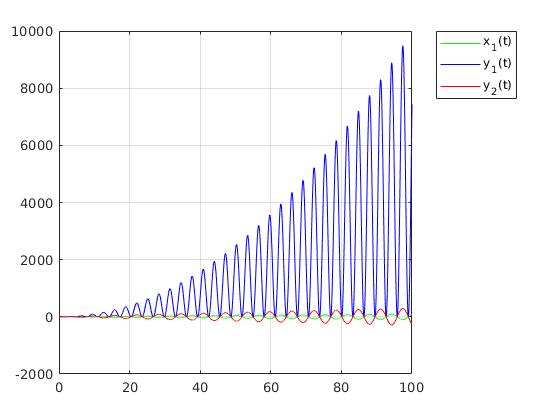

t = 0:0.01:4;
x1 = t.*cos(t);
y1 = x1.^2;
y2 = 1-3.*x1;
plot(t, x1, 'g',t, y1, 'b', t, y2, 'r')
legend('x_1(t)', 'y_1(t)', 'y_2(t)', "Location","bestoutside")
grid on

#### MIMO - Multiple-Input Multiple-Output 

d) Suponha que um sistema MIMO S  é descrito pelas relações de entrada saída $y_1 \left(t\right)=x_1 \left(t\right)+x_2 \left(t\right)$ e $y_2 \left(t\right)=x_1 \left(t\right)-x_2 \left(t\right)$. Compute e plot a saída do sistema se os sinais de entrada são dados por $x_1 \left(t\right)=u\left(t\right)$, $x_2 \left(t\right)=0\ldotp 5u\left(t-1\right)$, $0\le t\le 4$.

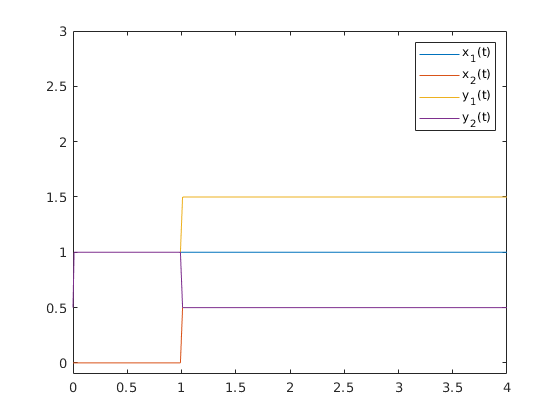

t = 0:0.01:4;
x1 = heaviside(t);
x2 = 0.5*heaviside(t-1);
y1 = x1 + x2;
y2 = x1 - x2;
plot(t, x1, t, x2, t, y1, t, y2)
ylim([-0.1 3])
legend('x_1(t)', 'x_2(t)', 'y_1(t)', 'y_2(t)')

### Propriedades de sistemas

#### Causal e não causal

e) Suponha que o sistema S1 é descrito pela relação de entrada saída $y_1 \left(t\right)=x\left(t+1\right)$enquanto que do sistema S2 é dada por $y_2 \left(t\right)=x\left(t-1\right)$. Considerando que o sinal de entrada é $x\left(t\right)=u\left(t\right)-u\left(t-1\right)$, $-3\le t\le 3$. Determine se os dois sistemas são causais.

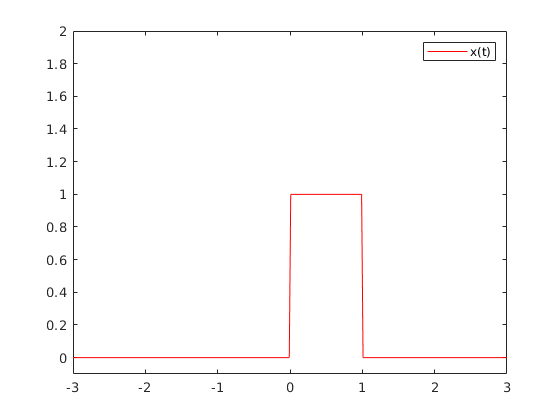

t = -3:0.01:3;
x = heaviside(t) - heaviside(t - 1);
figure
plot(t, x, 'r')
ylim([-0.1 2])
legend('x(t)')

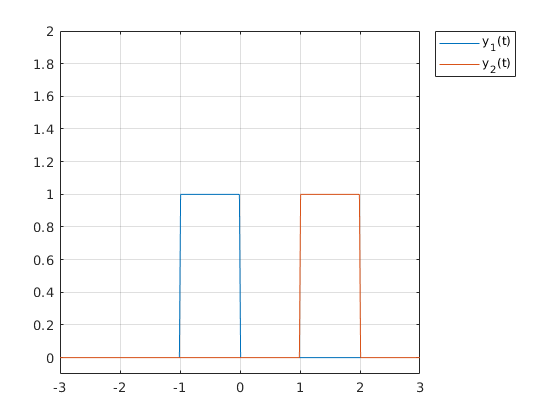

y1 = heaviside(t+1) - heaviside((t+1) - 1);
y2 = heaviside(t-1) - heaviside((t-1) - 1);
figure 
plot(t, y1, t, y2)
grid on
ylim([-0.1 2])
legend('y_1(t)', 'y_2(t)', "Location","bestoutside")

#### Estático (sem memória) e dinâmico (com memória)

f) Usando o sinal de entrada $x\left(t\right)=u\left(t\right)-u\left(t-1\right)$, $-3\le t\le 3$, determine se os sistemas descritos pelas relações de entrada saída $y_1 \left(t\right)=3x\left(t\right)$e $y_2 \left(t\right)=x\left(t\right)+x\left(t-1\right)$ são estático ou dinâmico.

t = -3:0.01:3;
x = heaviside(t) - heaviside(t - 1);
figure
plot(t, x, 'r')
ylim([-0.1 2])
legend('x(t)')

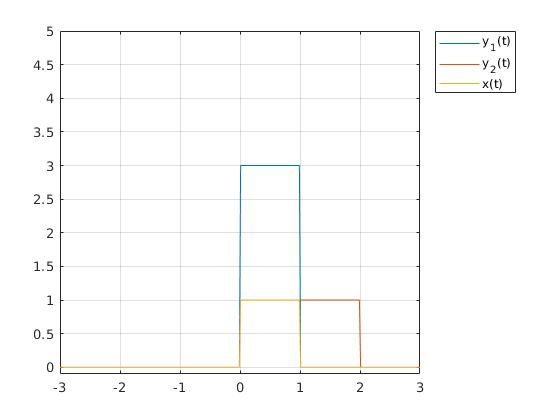


y1 = 3*x;
y2 = heaviside(t) - heaviside(t - 2);
figure 
plot( t, y1, t, y2, t, x)
grid on 
legend('y_1(t)', 'y_2(t)', 'x(t)', 'Location',"bestoutside")
%y1 é estatico, y2 é dinami
ylim([-0.1 5])

#### Linear e não linear


$$S\left\lbrace a_1 {\;x}_1 \left(t\right)+a_2 {\;x}_2 \left(t\right)\right\rbrace =a_1 S\left\lbrace x_1 \left(t\right)\right\rbrace \;+a_{2\;} S\left\lbrace x_2 \left(t\right)\right\rbrace$$


A resposta de um sistema linear para uma entrada que é a combinação linear de dois sinais corresponde a uma combinação linear das respostas do sistema para cada uma destes sinais de entrada. (Princípio da superposição = aditividade + homogenidade).

g) Dado $x_1 \left(t\right)=u\left(t\right)-u\left(t-1\right)$ e $x_2 \left(t\right)=u\left(t\right)-u\left(t-2\right)$ sejam considerados sinais de netrada para os sistemas descritos pelas seguintes relações $y\left(t\right)=2x\left(t\right)$ e $z\left(t\right)=x^2 \left(t\right)$, $-3\le t\le 3$. Determine se a propriedade de linearidade é válida para estes dois sistemas.

Solução: adotando os escalares $a_1 =2$ e $a_2 =3$

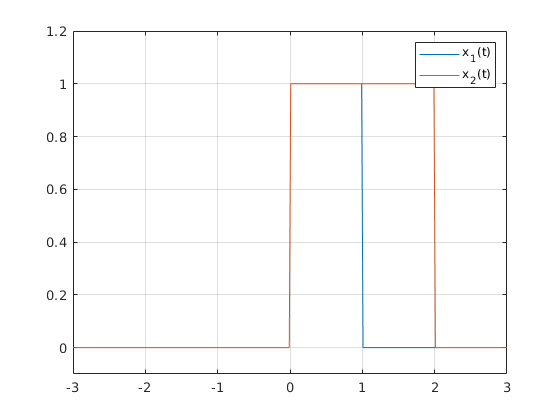

t = -3:0.01:3;
x1 = heaviside(t) - heaviside(t - 1);
x2 = heaviside(t) - heaviside(t - 2);
plot(t, x1, t, x2)
grid on
ylim([-0.1 1.2])
legend('x_1(t)', 'x_2(t)')

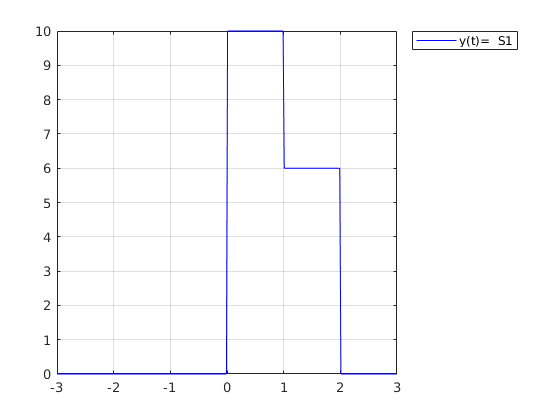

%Sistema 1 
a1 = 2;
a2 = 3;
s = a1 * x1 + a2 * x2;
ys = 2*s;
figure
plot(t, ys, 'b')
grid on
legend('y(t)=  S1', "Location","bestoutside")

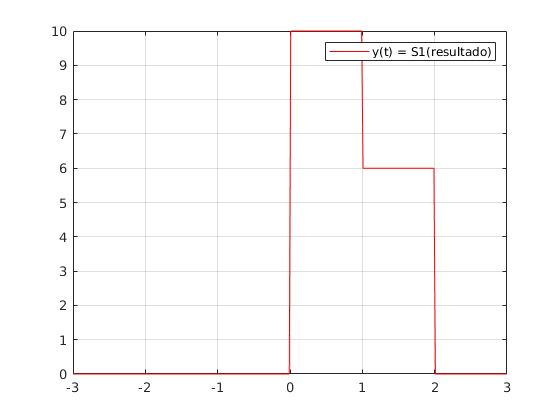

y1 = 2 * x1;
y2 = 2 * x2;
ys2 = a1 * y1 + a2 * y2;
plot(t, ys2, 'r')
grid on
%S1 É LINEAR
legend('y(t) = S1(resultado)')

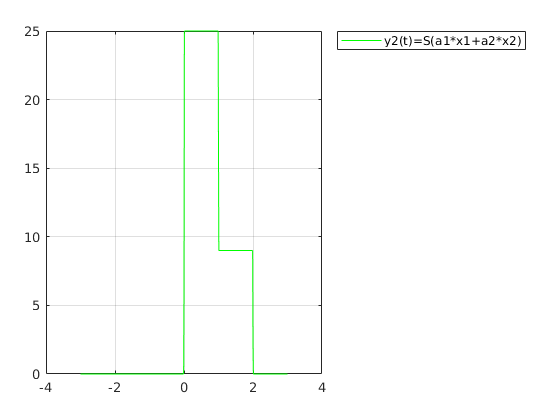

%S2 = y(t) = x(t)^2
% s = a1 * x1 + a2 * x2
z = s.^2;
plot(t, z, 'g')
grid on
legend('y2(t)=S(a1*x1+a2*x2)', "Location","bestoutside")

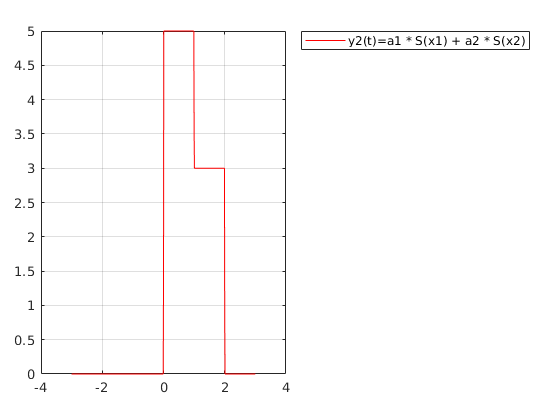

z1 = x1.^2;
z2 = x2.^2;
zs2 = a1 * z1 + a2 * z2;
plot(t, zs2, 'r')
grid on
legend('y2(t)=a1 * S(x1) + a2 * S(x2)', "Location","bestoutside")

#### Invariante no tempo e variante no tempo

Se $y\left(t\right)$é a resposta de um sistema invariante no tempo para uma entrada $x\left(t\right)$, então a resposta do sistema para um sinal de entrada $x\left(t-t_0 \right)$é $y\left(t-t_0 \right)$.


$$y\left(t-t_0 \right)=S\left\lbrace x\left(t-t_0 \right)\right\rbrace$$


h) Suponha que a resposta de um sistema S para um sinal de entrada $x\left(t\right)$é $y\left(t\right)={t\;e}^{-t} x\left(t\right)$. Determine se este sistema é invariante no tempo para uma entrada $x\left(t\right)=u\left(t\right)-u\left(t-5\right)$, $-3\le t\le 10$.

        1. Avaliar $y\left(t\right)=S\left\lbrace x\left(t\right)\right\rbrace$

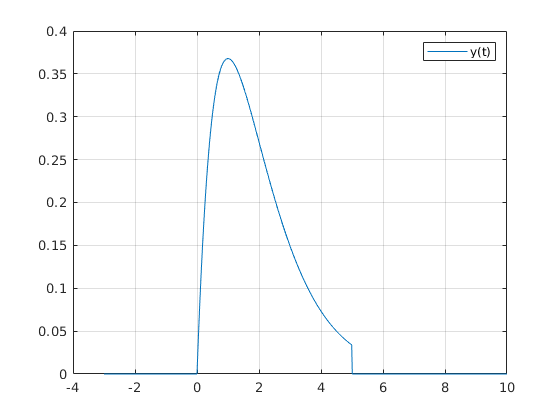

t = -3:0.01:10;
x = heaviside(t) - heaviside(t-5);
y = t.*exp(-t).*x;
figure
plot(t, y)
grid on
legend('y(t)')

        2. Obter $y\left(t-t_0 \right)$, $t_0 =3$

figure
plot(t+3, y)
grid on
hold on

        3. Obter $S\left\lbrace x\left(t-t_0 \right)\right\rbrace$, $t_0 =3$ e comparar com o passo 2.

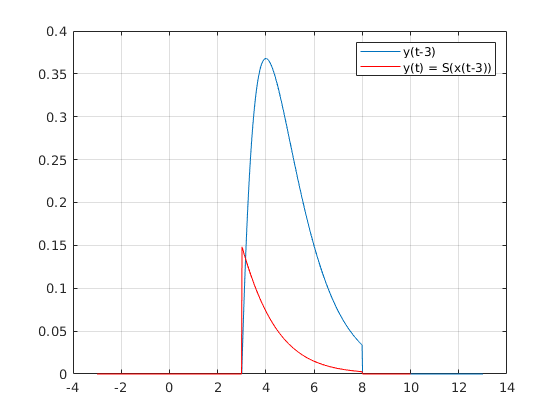

%Este sistema é variante no tempo
t = -3:0.01:10;
x = heaviside(t-3) - heaviside((t-3)-5);
y = t.*exp(-t).*x;
plot(t, y, 'r')
grid on
legend('y(t-3)', 'y(t) = S(x(t-3))')

#### Estável e instável

BIBO - *Bounded-Input Bounded Output*

Para um pequeno sinal aplicado na entrada a resposta do sistema também é pequena e não diverge. Ou seja, se um dado número positivo existe $M<\infty$, tal que $\left|x\left(t\right)\right|\le M$. O sistema é estável se $\forall t\in \Re$ um número positivo $N<\infty$, tal que $\left|y\left(t\right)\right|\le N$.

i) Suponha que um sinal de entrada $x\left(t\right)=\cos \left(2\pi \;t\right)$é aplicado a dois sistemas descritos pela relação de entrada saída $y_1 \left(t\right)=x^2 \left(t\right)$e $y_2 \left(t\right)=t\;x\left(t\right)$, $0\le t\le 10$. . Determine se estes sistemas são estáveis.

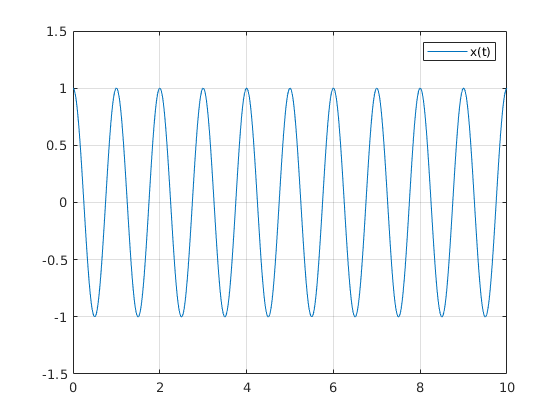

t = 0:0.01:10;
x = cos(2*pi*t);
figure
plot(t, x)
ylim([-1.5 1.5])
grid on
legend('x(t)')

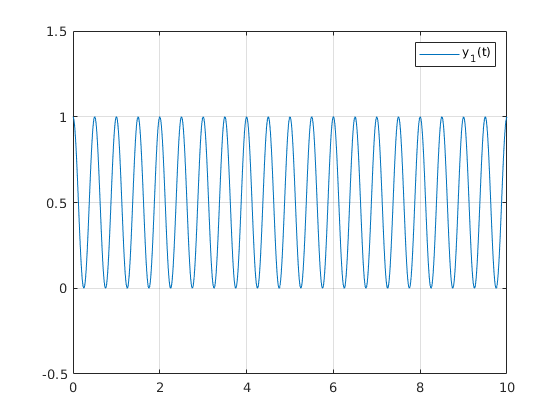

%Sistema 1 (É estavel): 
y1 = x.^2;
plot(t, y1)
grid on 
ylim([-0.5 1.5])
legend('y_1(t)')

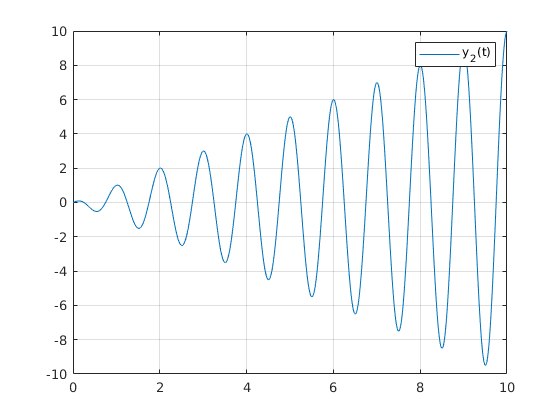

%Sistema 2 (É instavel):
y2 = t.*x;
plot(t, y2)
grid on
legend('y_2(t)')

#### Invertível e não invertível

Um sistema é invertível se um sinal de entrada $x\left(t\right)$que é aplicado ao sistema pode ser derivado a partir da resposta do sistema $y\left(t\right)$. Ou seja, um sistema é invertível se a relação entrada saída $y\left(t\right)=S\left\lbrace x\left(t\right)\right\rbrace$é uma para uma, isto é, diferentes valores de entrada correspondem a distintos valores de saída.

j) Determine se os sistemas S1 e S2 descritos pelas relações de entrada saída $y_1 \left(t\right)=3x\left(t\right)$e $y_2 \left(t\right)=x^2 \left(t\right)$, respectivamente, são invertíveis. Considere $x\left(t\right)=2\;t$, $-2\le t\le 2\ldotp$

t = -2:2;
x = 2*t

x =     -4    -2     0     2     4


y1 = 3*x

y1 =    -12    -6     0     6    12


y2 = x.^2

y2 =     16     4     0     4    16


- Sistema inverso

            
$$z\left(t\right)=S^{-1} \left\lbrace y\left(t\right)\right\rbrace$$


%É invertível
z1 = 1/3*y1

z1 =     -4    -2     0     2     4


%Não é invertível
z2 = sqrt(y2)

z2 =      4     2     0     2     4
